# Extract COM trajectory from 

In [this paper from ASME](https://sci-hub.se/10.1115/DSCC2017-5261), the figure shown below demonstrates how a human's center of mass (COM) moves while performing sit-to-stand (STS) movement. The human subject between age of 25 to 30 with mass 100kg and height of 1.75m was used. The STS transition can be visualized by the trajectory followed by the COM of the whole body in the sagittal plane.

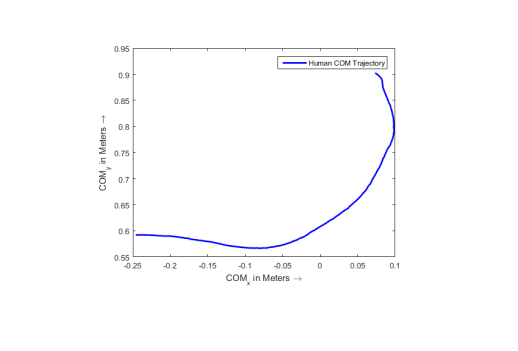

clf, close all
imshow("fig_COMTraj.jpg")

xlims = [-0.25 0.1]; % limits in x-axis
ylims = [0.55 0.95]; % limits in y-axis

The image is extracted using erosion with cross-shape structuring element. From the result below, MATLAB does not know this curve is a trajectory in 2D space. Thus, the curve is divided into 2 parts. The first part has $x_1 \approx -0\ldotp 25\div 0\ldotp 1$ and $y_1 \approx 0\ldotp 6\div 0\ldotp 7$. The second part has $x_2 \approx 0\ldotp 1\div 0\ldotp 2$ and $y_2 \approx 0\ldotp 7\div 0\ldotp 95$. 

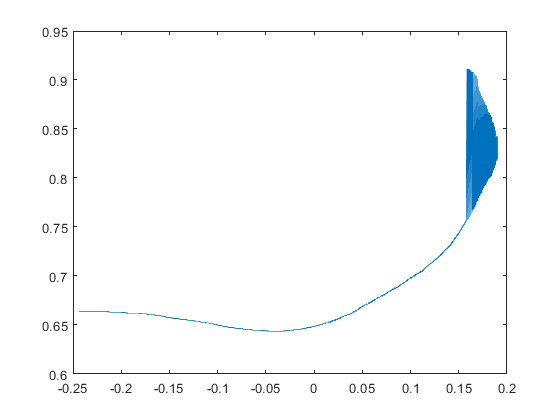

R = imread('edited_COMTraj.jpg');
R = rgb2gray(R);
R = 1-imbinarize(R);
se = [0 1 0
      1 1 1
      0 1 0];
out = imerode(R, se);
% extract x,y axes
imxmax = size(R,1);
imymax = size(R,2);
[imy,imx] = find(out);
xCOM = imx/imxmax*diff(xlims) + xlims(1);
yCOM = (imymax-imy)/imymax*diff(ylims) + ylims(1);

figure
plot(xCOM,yCOM)

% extract the first part
imxlim_loc1 = 1:imxmax;
imylim_loc1 = 1:349;
im_loc1 = out(imxlim_loc1,imylim_loc1);

[imx1,imy1] = find(im_loc1);
x1 = imylim_loc1(1) - 1 + imy1;
y1 = imxlim_loc1(1) - 1 + imxlim_loc1(end) - imx1;

% extract the second part
imxlim_loc2 = 1:imxmax;
imylim_loc2 = 350:imymax;
im_loc2 = out(imxlim_loc2,imylim_loc2);

[imy2,imx2] = find(im_loc2');
x2 = imylim_loc2(2) - 2 + flip(imy2);
y2 = imxlim_loc2(2) - 2 + imxlim_loc2(end) - flip(imx2);

The 2 parts are combined into a complete trajectory. 

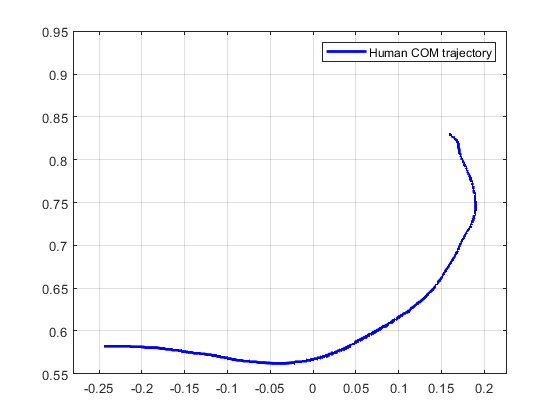

imx = [x1; x2];
imy = [y1; y2];
xCOM = imx/imxmax*diff(xlims) + xlims(1);
yCOM = imy/imymax*diff(ylims) + ylims(1);

plot(xCOM,yCOM,'b-','LineWidth',2)
legend('Human COM trajectory')
xlim(xlims), ylim(ylims)
axis equal, grid on

% save the trajectory in .mat file
save Data/COM_Trajectory/COMTraj.mat xCOM yCOM